# TALLER 11 EVALUABLE Ecuaciones diferenciales 

Sofia Suarez 

Octubre 1 de 2023

Ecuaciones diferenciales 

Clase: lunes 1:30 pm 

**INTRODUCCION: **El objetivo de este taller es resolver numéricamente, la ecuación de estado de un modelo epidemiológico [SIRV](https://en.wikipedia.org/wiki/Compartmental_models_in_epidemiology#The_SIRV_model) (SIR con vacunados) no lineal en un archivo Live Script de MATLAB y analizar el resultado. A continuacion la explicacion del problema planteado. 

Modelo matemático

             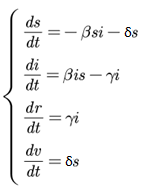

Supuestos: población cerrada (no llegan personas de otros lugares) y constante (*s* + *i* + *r* + *v* = 1), población uniforme, mezcla homogénea (sin consideraciones de edad, distribución espacial, educación o estructura social).

Donde, *s* es el porcentaje de personas susceptibles (pueden contraer la enfermedad), *i* es el porcentaje de personas infectadas, *r* es el porcentaje de personas recuperadas (y que no vuelven a contraer la enfermedad, es decir, quedan inmunes) y *v* es el porcentaje de personas vacunadas.

β es la tasa de transmisión, γ es la tasa de recuperación y aislamiento, y δ es la tasa de vacunación.

Observar que se tiene una epidemia creciente si (igual que en el caso SIR):

        

*R*0 es el número reproductivo básico.

Caso para estudiar (hay epidemia, *R*0 > 1): β = 0.1, γ = 0.02, δ = 0.001, *s*(0) = 0.8, *i*(0) = 0.1, *r*(0) = 0, *v*(0) = 0.1

**METODOLOGIA: **Se plantena 5 ejercicios, similares entre si. Estos ejercicios nos permiten entender como funciona cada variable y al analizar las graficas entendemos en que afecta exactamente cada una de ellas. esto se estara relaizando por el método numérico de Runge-Kutta implementado en la función [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) de MATLAB y por medio de ecuaciones de estado. Adicionalmente se aplicara todo lo visto en las clases de taller de la materia. 

**PUNTOS A RESOLVER **

- Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)?

- Graficar sólo la solución *i*(*t*) con un aumento sólo de *i*(0) y usando al menos 5 valores. Observar que al cambiar *i*(0) cambia *s*(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.

- Graficar sólo la solución *i*(*t*) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.

- Graficar sólo la solución *i*(*t*) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.

- Graficar sólo la solución *i*(*t*) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? Interpretar los resultados.

**Primer punto: **Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)?

syms s(t) i(t) r(t) v(t)
beta = 0.1;
gamma = 0.02;
delta = 0.001;

eq1 = -beta*s*i-delta*s; %suseptibles  s
eq2 = beta*s*i - gamma*i; %infectados  i
eq3 = gamma*i; %recuperados  r
eq4 = delta*s;

% Usamos el comando ODE45 para resolver
F = odeFunction ([eq1 eq2 eq3 eq4], [s i r v]);

%tiempo
t0 = 0;
tf = 365;

%paso
h = 0.1;
t =t0:h:tf;

%condicion inicial 
ci = [0.8 0.1 0 0.1];
% Resolver usando el comando ODE45
[t, sol] = ode45(F,t,ci);

s_sol = sol(:,1); %en un amtriz todas las filas de la primera colmna
i_sol = sol(:,2);
r_sol = sol(:,3);
v_sol = sol(:,4);

%grafica
figure 
plot(t, s_sol) %con plot pq no son soluciones simbolicas sino numericas 
hold on 
plot(t,i_sol)
plot(t,r_sol)
plot(t,v_sol)
xlabel('Tiempo (seg)')
ylabel ('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie')
legend('S(t)','I(t)','R(t)','V(t)')
grid on

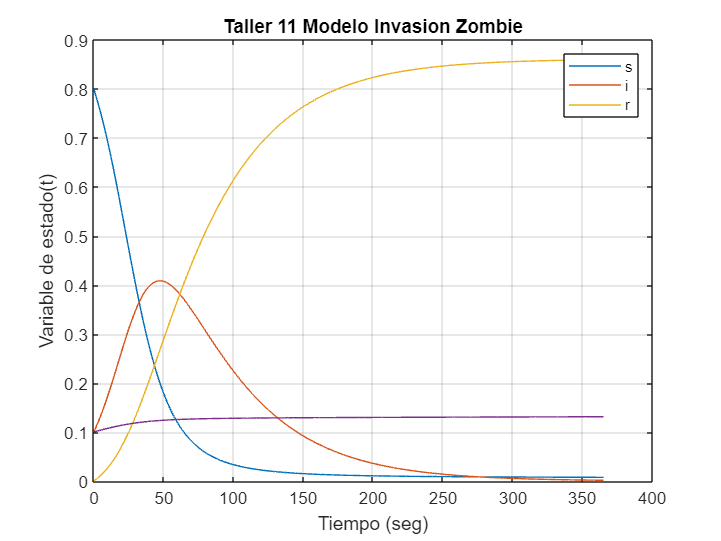

legend("s","i","r")

**Conclusiones **

**Resultados: **

- Podemos ver que el pico de infectados alcanza hasta o.4 de la poblacion 

- el crecimiento de los infectados mas los vacunados es proporcional al decrecimiento de los suceptibles

- Podemos ver que los suceptibles disminuyen y se estabilizan de manera rapida

- Podemos ver que la tasa de vacunados aumenta lentamente 

**Analisis:**

- Con el tiempo hay menos personas suceptibles, estos pasan a infectarse o directamente a vacunarse , por esto se puede observar el decrecimiento de la poblacion suceptible, es casi de la misma proporcion del crecimiento de los infectados mas la de los vacunados. 

- La razon por la que la curva en vacunados aumnete tan lentamente, es debido a que la taza de vacunacion es muy pequeña (0.01) indicando al 10% de la poblacion 

Cambiamos las condiciones iniciales para que el pico disminuya un 50% al aumentar la tasa de vacunacion 

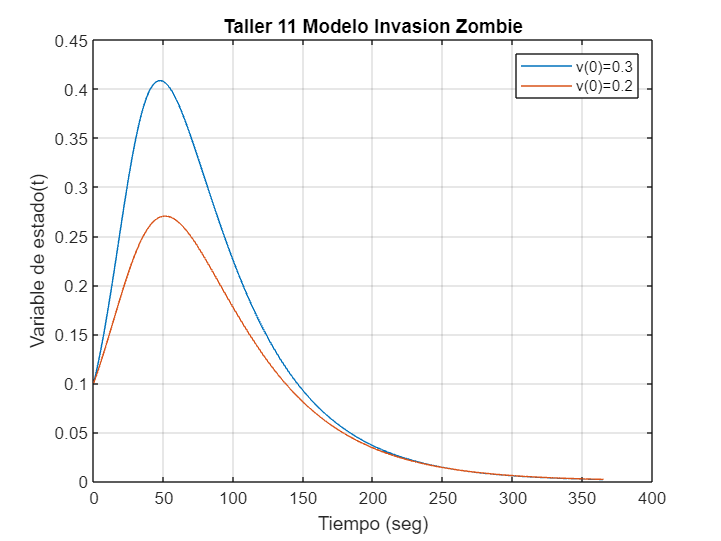

v0 = 0.3;
ci = [0.9-v0 0.1 0 v0];
[t2,sol] = ode45(F,t,ci);
i_sol2 = sol(:,2);

figure
plot(t,i_sol,t2,i_sol2)
xlabel('Tiempo (seg)')
ylabel ('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie')
grid on
legend({['v(0)=' num2str(v0)];'v(0)=0.2'})

**Conclusiones **

**Resultados:**

- Podemos ver que la curva asul tiene un pico casi el doble de la curva roja, azul en y=0.41 y rojo en y=0.27

- Ambas curvas se unifican en x=225 

**Analisis:**

- Podemos decir que a medida que se va aumentando la tasa de vacunacion, disminuye la curva de infectados 

- A pesar de que la curva de infectados son diferentes, estos se recuperan en el mismo tiempo 

a medida de que aumenta la tasa de vacunacion disminuye el pico de vacunados 

**Segundo punto: **Graficar sólo la solución *i*(*t*) con un aumento sólo de *i*(0) y usando al menos 5 valores. Observar que al cambiar *i*(0) cambia *s*(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.

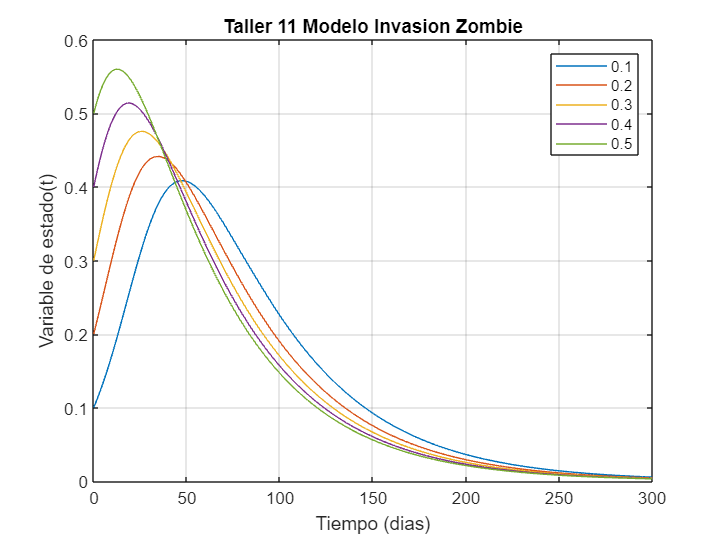

syms s(t) i(t) r(t) v(t)
beta = 0.1;
gamma = 0.02;
delta = 0.001;

eq1 = -beta*s*i-delta*s; %suseptibles  s
eq2 = beta*s*i - gamma*i; %infectados  i
eq3 = gamma*i; %recuperados  r
eq4 = delta*s;

% usamos el comando ODE45 para resolver
F = odeFunction ([eq1 eq2 eq3 eq4], [s i r v]);

%tiempo
t0 = 0;
tf = 300;

%paso
h = 0.1;
t =t0:h:tf;

%condicion inicial 
% Como vamos a resolver numericamente armamos el vector de condiciones
Multipleci = [0.8 0.1 0 0.1 %suseptible infectrados recuperados vacunados 
              0.7 0.2 0 0.1
              0.6 0.3 0 0.1
              0.5 0.4 0 0.1
              0.4 0.5 0 0.1];

%solucion metod numrico 
figure
for i = 1:length(Multipleci)
    % Resolver usando el comando ODE45
    [t, sol] = ode45(F,t,Multipleci(i,:)); %con todas las variables de la matriz
    i_sol = sol(:,2);     %en un amtriz todas las filas de la primera colmna, math lab funciona como fila, col
    plot(t,i_sol)
    hold on 
        
end 
legend(num2str(Multipleci(:,2)))
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie')
grid on

**Conclusiones **

**Resultados:**

- A medida que aumentamos el valor de infectados, esto nos muestra en la grafica un un pico mas pronunciado 

- Podemos ver que entre mas grande sea la curva, o el pico mas pronunciado, meor tiempo tardan encurarse 

**Analisis:**

- Para este ejercicio se utilizo una matriz comparativa que va aleterando los valores de las condiciones iniciales de infectados, suceptibles, recuperados y vacunados. con relacion a lo que se dijo anteriormente cuando comenzamos con un valor mas alto de personas infectadas (0.5) la curva es mas produnciada pero el tiempo en el que disminuye, en este caso x=200 aproximadamente es mas bajo que los demas  

**Tercer punto: **Graficar sólo la solución *i*(*t*) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.

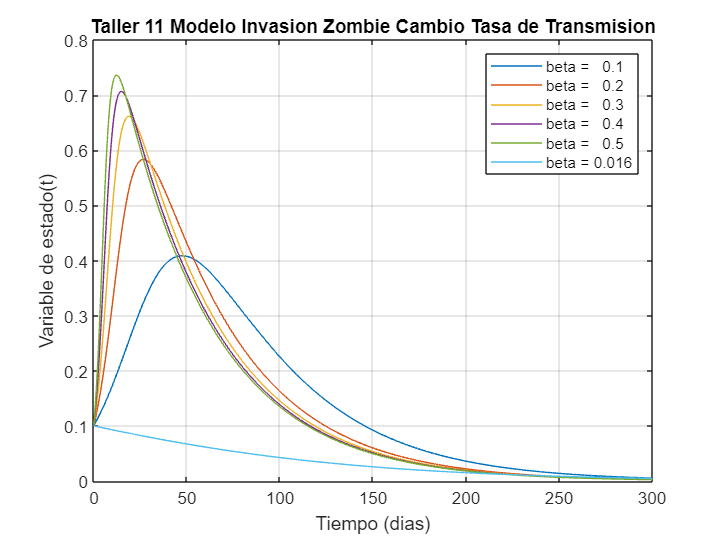

syms s(t) i(t) r(t) v(t)
beta =  [0.1 0.2 0.3 0.4 0.5 0.016];
gamma = 0.02;
delta = 0.001;

%tiempo
t0 = 0;
tf = 300;

%paso
h = 0.1;
t =t0:h:tf;

%condicion inicial 
ci = [0.8 0.1 0 0.1];

%solucion metod numrico 
figure
for j = 1:length(beta)
    eq1 = -beta(j)*s*i-delta*s; %suseptibles  s
    eq2 = beta(j)*s*i - gamma*i; %infectados  i
    eq3 = gamma*i; %recuperados  r
    eq4 = delta*s; %vacunados v 
    
    % usamos el comando ODE45 para resolver  
    F = odeFunction ([eq1 eq2 eq3 eq4], [s i r v]);
    % Resolver usando el comando ODE45
    [t, sol] = ode45(F,t,ci);
    i_sol = sol(:,2);     %en un amtriz todas las filas de la primera colmna, math lab funciona como fila, col
    plot(t,i_sol)
    hold on 

end 
legend("beta = " +  num2str(beta'))
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie Cambio Tasa de Transmision')
grid on 

**Conclusiones **

**Resultados:**

- podemos ver que cuando el valor de beta aumenta, el pico e la curva aumenta simultaneamente 

- Asimismo podemos ver que cuando la curva es mas pronunciada tiende a disminuir y equilibrarse en un menor tiempo 

- La curva del valor 0.016 no tiene un pico 

- Todas las curvas de la grafica comienzan en 0.1

**Analisis: **

- Para obtener el valor de 0.016 utilizamos la formula  despejamos beta y conseguimos el valor 

- El valor de 0.016 no presenta un pico ya que su valor es menor a 0.1 y todas las curvas comienzan en este valor 

**Cuarto punto: **Graficar sólo la solución *i*(*t*) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.

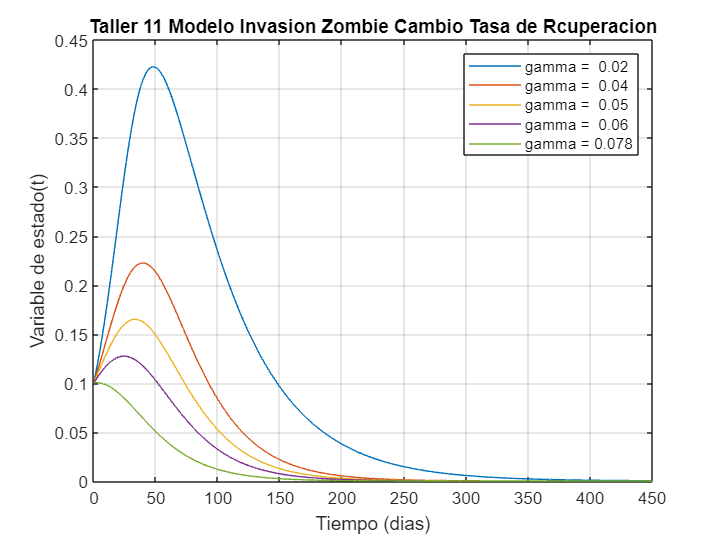

syms s(t) i(t) r(t) v(t)
beta = 0.1;
gamma = [0.02 0.04 0.05 0.06 0.078];
delta = 0.001;

%tiempo
t0 = 0;
tf = 450;
h = 0.1;
t =t0:h:tf;

%condicion inicial 
ci = [0.8 0.1 0 0.1];


%solucion metod numrico 
figure
for gamma1 = gamma
    eq1 = -beta*s*i; %suseptibles  s
    eq2 = beta*s*i - gamma1*i; %infectados  i
    eq3 = gamma1*i; %recuperados  r
    eq4 = delta*s; %vacunados v 
      
    % usamos el comando ODE45 para resolver
    F = odeFunction ([eq1 eq2 eq3 eq4], [s i r v]);
    % Resolver usando el comando ODE45
    [t,sol] = ode45(F,t,ci);

    i_sol = sol(:,2);     %en un amtriz todas las filas de la primera colmna, math lab funciona como fila, col
    plot(t,i_sol)
    hold on 

end 
legend("gamma = " +  num2str(gamma'))
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie Cambio Tasa de Rcuperacion')
grid on

**Conclusiones **

**Resultados:**

- En este caso podemos ver que cuando el valor de gamma disminuye el pico de la curva es mayor 

- Asimismo podemos ver que cuando la curva es mas pronunciada y se demora mas tiempo en estabilizarse 

- Todas las curvas de la grafica comienzan en 0.1

**Analisis: **

- La curva con el valor de (0.1) no tiene ningun pico de infeccion debido a que la tasa de recuperacion es muy grande 

- A medidia de que el valor de gama disminuye el pico es mucho mas pronunciado, esto debido a qeu gamma nos muestra la tasa de recuperados, y si esta es menor habran mas infectados 

- Para obtener el valor de 0.078 utilizamos la formula  despejamos gamma y conseguimos el valor 

**Quinto punto: **Graficar sólo la solución *i*(*t*) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? Interpretar los resultados.

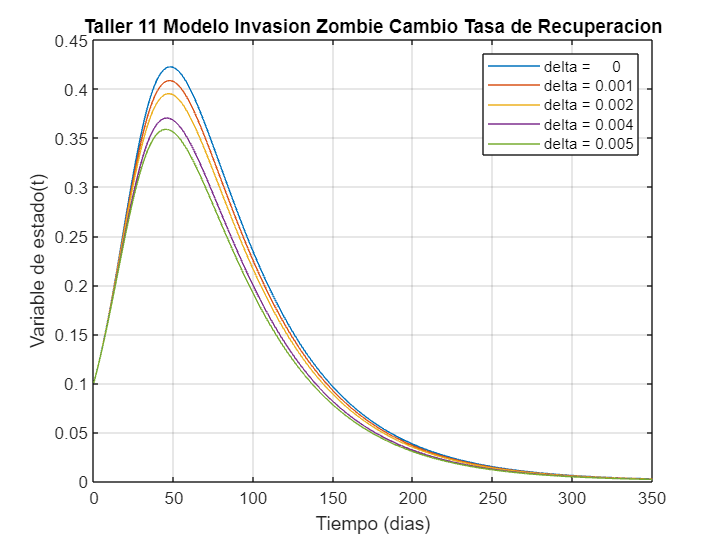

% Definición de variables.
syms s(t) i(t) r(t) v(t)

beta = 0.1; 
gamma = 0.02; 
delta = [0.00, 0.001, 0.002, 0.004, 0.005];

t0 = 0;
tf = 350;
h = 0.1;
t = t0:h:tf;

%condicion iniciales.
ci = [0.8 0.1 0 0.1]; 

%Ecuaciones 
figure
for delta1=delta
    eq1 = -s*i*beta - delta1*s; %susepctible s
    eq2 = s*i*beta - gamma*i; %infectados i
    eq3 = gamma*i; %recuperados r
    eq4 = delta1*s; %vacunados v 

    % usamos el comando ODE45 para resolver
    F = odeFunction([eq1, eq2, eq3, eq4], [s i r v]);
    % Resolver usando el comando ODE45
    [t,sol] = ode45(F,t,ci); 

    i_sol = sol(:,2);     %en un amtriz todas las filas de la primera colmna, math lab funciona como fila, col
    plot(t,i_sol)
    hold on 

end 

legend("delta = " +  num2str(delta'))
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie Cambio Tasa de Recuperacion')
grid on

**Resultados**

- El valor de delta y el pico de infectados es inversamente proporcional 

- Podemos ver que todas las curvas se estabilizan simultaneamente aproximadamente en X=300

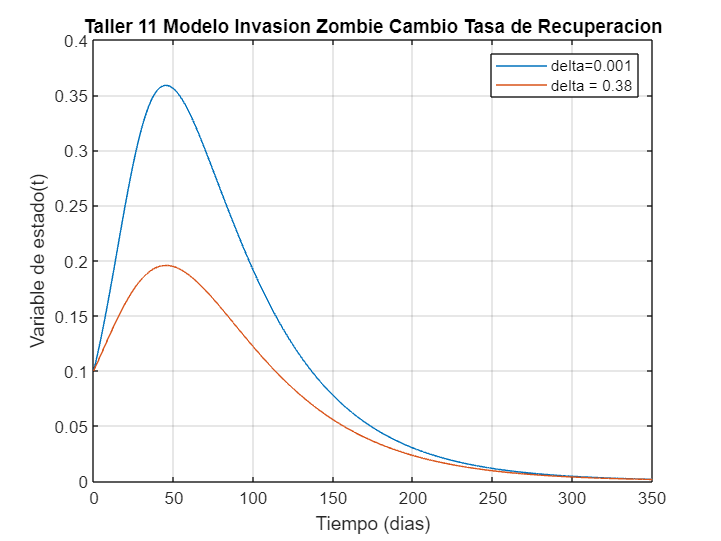

delta1 = 0.38;

%condicion iniciales.
ci = [0.9-delta1 0.1 0 v0]; 
[t2,sol2] = ode45(F,t,ci); 
i_sol2 = sol2(:,2);     %en un amtriz todas las filas de la primera colmna, math lab funciona como fila, col
   
%grafica
figure
plot(t,i_sol, t2,i_sol2)
hold on 
legend({'delta=0.001',["delta = " +  num2str(delta1')]})
xlabel('Tiempo (dias)')
ylabel ('Variable de estado(t)')
title('Taller 11 Modelo Invasion Zombie Cambio Tasa de Recuperacion')
grid on

**Conclusiones **

**Resultados:**

- Todas las curvas de la grafica comienzan en y=0.1

- Al igual que en la grafica anterior delta es inversamente proporcional a el pico 

- uando el valor de delta es 0.38, se culple la disminusion del 50% del pico 

- Todas las curvas se estabilizan en x=300 

**Analisis:**

- A medida de que sean mas el porcentaje de vacunados sera menor el porcentaje de infectados, por esto la epidemia baja cuando aumentamos la tasa de vacunacion, siguiendo esta logica los infectados disminuye devido a que después de vacunarse quedan imunes. 

- Se debe vacunar a una tasa del 0.38 para que el pico disminuya un 50% comparado al valor inicia 